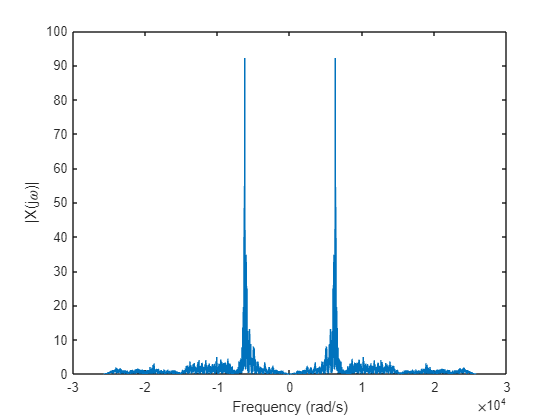

ans =   -0.0370 + 0.0000i
  -0.0468 - 0.0010i
  -0.0577 + 0.0040i
  -0.0641 + 0.0205i
  -0.0570 + 0.0359i
  -0.0362 + 0.0622i
  -0.0174 + 0.0608i
   0.0049 + 0.0581i
   0.0328 + 0.0488i
   0.0486 + 0.0159i


%load short_modem_rx.mat 
load short_modem_rx.mat
% The received signal includes a bunch of samples from before the
% transmission started so we need discard these samples that occurred before
% the transmission started. 

start_idx = find_start_of_signal(y_r,x_sync);
% start_idx now contains the location in y_r where x_sync begins
% we need to offset by the length of x_sync to only include the signal
% we are interested in
y_t = y_r(start_idx+length(x_sync):end); % y_t is the signal which starts at the beginning of the transmission

c = cos(2*pi*f_c/Fs*[0:length(y_t)-1]');
%plot(t, cos_c)
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%  Put your decoder code here
%%

%soundsc(y_t, Fs)
plot_ft_rad(y_t, Fs)

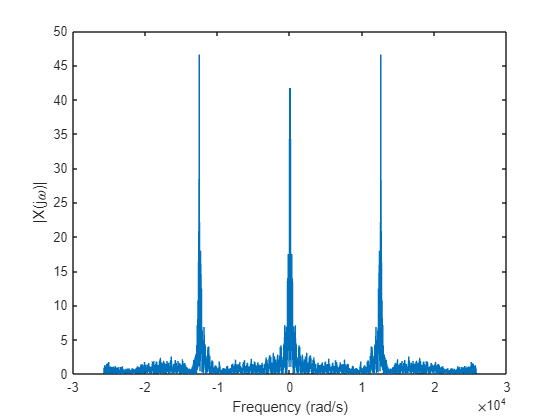

ans =   -0.0914 + 0.0000i
  -0.0037 + 0.1004i
   0.1201 + 0.1982i
   0.2338 + 0.2046i
   0.3002 + 0.1222i
   0.2833 + 0.0143i
   0.2520 - 0.0542i
   0.2101 - 0.0736i
   0.1309 - 0.0628i
   0.0938 + 0.0090i


new_y = y_t.*c;
%soundsc(new_y, Fs)

plot_ft_rad(new_y, Fs)

cutoff = 2*pi*f_c %Set the cutoff frequency for the low-pass filter

cutoff = 6.2832e+03

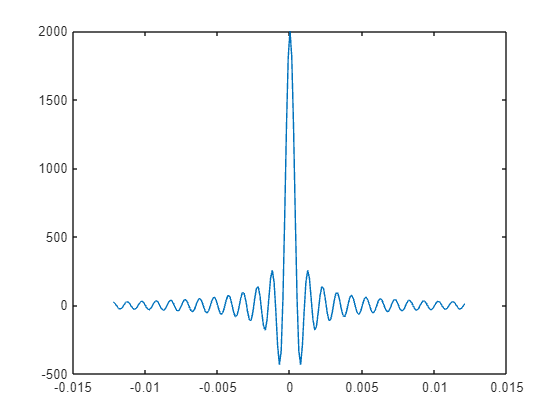



%Setup Low Pass Filter%
W = cutoff;	% set the cutoff frequency to 2 pi * 1000 rads/s
t = [-100:1:99]*(1/Fs);   % create a 200 sample time vector to generate sinc
h = W/pi*sinc(W/pi*t);   % this is the impulse response
plot(t, h);   	% plot h to visualize


figure
plot_ft_rad(h, Fs)  % Visualize |H(j\omega)|

ans = 1.0e+03 *

   0.0027 + 0.0000i   0.0027 - 0.0000i   0.0027 + 0.0000i   0.0027 - 0.0000i   0.0027 + 0.0000i   0.0027 - 0.0000i   0.0027 + 0.0000i   0.0027 + 0.0000i   0.0027 - 0.0000i   0.0027 + 0.0000i   0.0027 + 0.0000i   0.0028 + 0.0000i   0.0028 - 0.0000i   0.0028 - 0.0000i   0.0028 + 0.0000i   0.0028 + 0.0000i   0.0029 - 0.0000i   0.0029 - 0.0000i   0.0029 - 0.0000i   0.0030 + 0.0000i   0.0030 - 0.0000i   0.0030 + 0.0000i   0.0031 + 0.0000i   0.0031 - 0.0000i   0.0031 + 0.0000i   0.0032 - 0.0000i   0.0032 + 0.0000i   0.0033 - 0.0000i   0.0034 - 0.0000i   0.0034 - 0.0000i   0.0035 + 0.0000i   0.0035 + 0.0000i   0.0036 - 0.0000i   0.0037 - 0.0000i   0.0038 + 0.0000i   0.0039 - 0.0000i   0.0040 - 0.0000i   0.0041 + 0.0000i   0.0042 - 0.0000i   0.0043 - 0.0000i   0.0044 - 0.0000i   0.0045 - 0.0000i   0.0047 + 0.0000i   0.0048 + 0.0000i   0.0050 + 0.0000i   0.0051 + 0.0000i   0.0053 - 0.0000i   0.0055 - 0.0000i   0.0057 - 0.0000i   0.0060 - 0.0000i


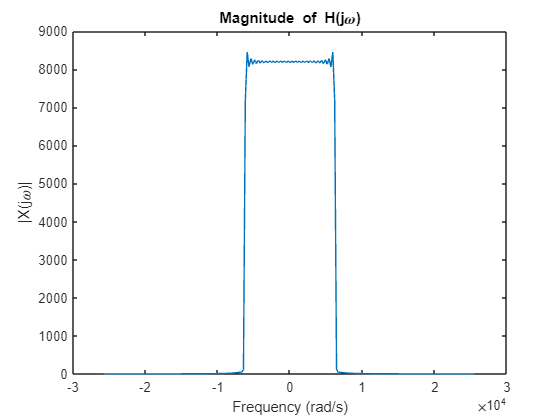

title('Magnitude of H(j\omega)');

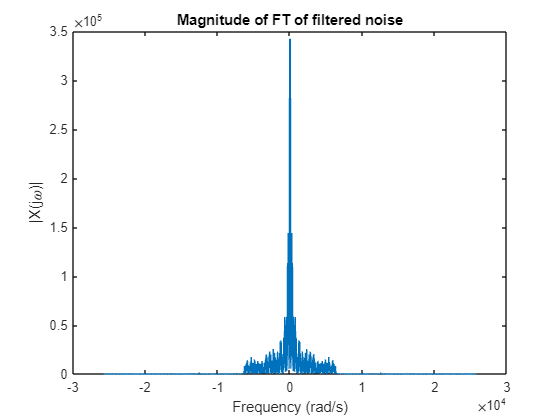

 
filtered_y = conv(new_y, h);     % convolve x with h to filter the noise

%  Butter low-pass filter
% [b, a] = butter(6, f_c/(Fs/2));  % 6th order Butterworth filter
% filtered_y = filtfilt(b, a, new_y);

figure
plot_ft_rad(filtered_y, Fs); % plot the magnitude of the FT of the filtered noise
title('Magnitude of FT of filtered noise');

soundsc(filtered_y, Fs);	% listen to the filtered noise

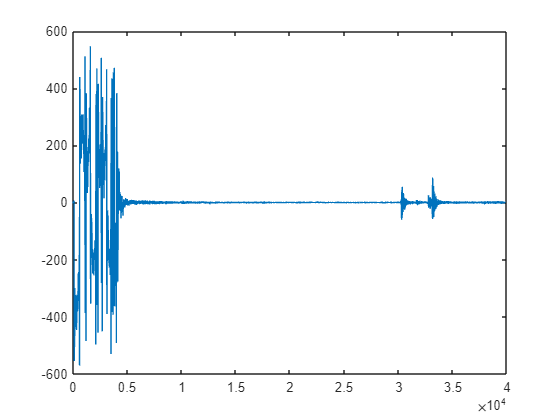

% Dynamic thresholding based on the noise level or median value
threshold = median(abs(filtered_y)) * 1.5;
y_square = double(abs(filtered_y) > threshold);
clf
plot(filtered_y)

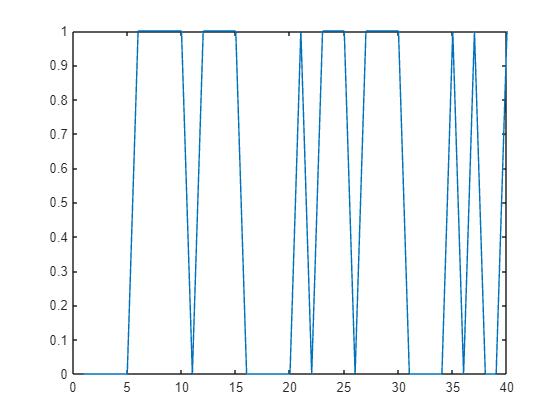

plot(y_sqaure)

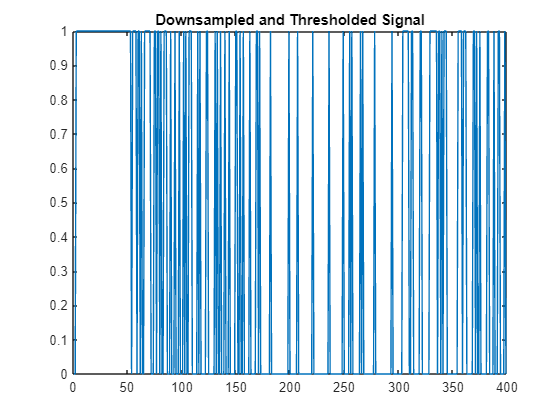


% Downsampling correctly based on SymbolPeriod
downsampled_y_square = downsample(y_square, 100);

% Plot to check the processed signal
clf;
plot(downsampled_y_square);
title('Downsampled and Thresholded Signal');


% Ensure the decoded bits are ready for conversion
if mod(length(downsampled_y_square), 8) ~= 0
    downsampled_y_square = downsampled_y_square(1:floor(length(downsampled_y_square)/8)*8);
end

% Convert to string
decoded_message = BitsToString(downsampled_y_square);
disp(['Decoded Message: ', decoded_message]);

Decoded Message: A@Øô□àÐÀà¶êÇ□Ã□□áÃãÄÀÔ□□¸ãÃ□ÁÀ□Á¤□òÂÂ¢□□Â □□Á¢□□Ç
